# Detect Outer Race Faults

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 4

To test that your metric works, you can apply it on another signal. Since the metric is looking for broken fans, the metric value should be small with the working fan signal.

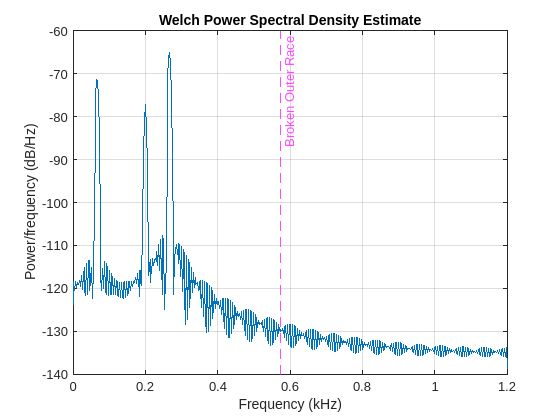

load("./data/psdsig.mat")
pwelch(sig,[],[],[],fs)
frO = 143.13;
xline(frO*4/1000,"m--","Broken Outer Race")

## Task 1

To check for outer race faults, you can filter fan vibration signals using a bandpass filter.

In this project, you'll use the dropdown at the top of the script to apply the same filter to a working fan and a broken fan. Both signals will be stored in a variable named `sig`.

First, you can design the filter.

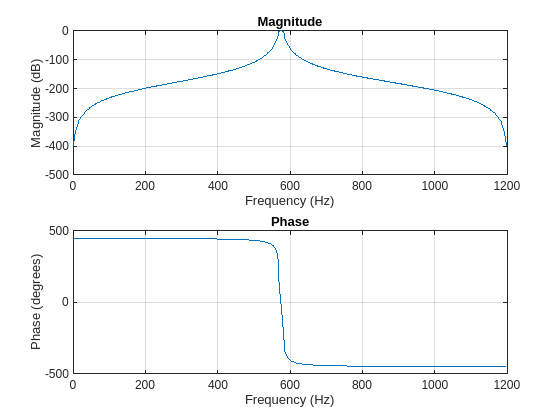

% Design a digital filter
bpFilt = designfilt('bandpassiir', ...
    'StopbandFrequency1',500,'PassbandFrequency1',570, ...
    'PassbandFrequency2',580,'StopbandFrequency2',600, ...
    'StopbandAttenuation1',60,'PassbandRipple',1, ...
    'StopbandAttenuation2',60,'SampleRate',fs);

% Visualize magnitude and phase responses
freqz(bpFilt.Coefficients,[],fs)

## Task 2

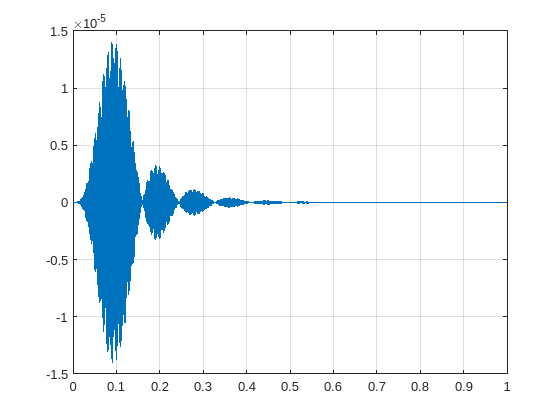

sigfilt = filter(bpFilt,sig);
plot(t,sigfilt)
grid on

## Task 3

As you might expect, the broken fan signal still has lots of content after filtering out outer race frequency content. In order to quickly categorize the signals as working or broken, you can develop a threshold metric. In this project, you'll use:

`mean``(``s``.^``2``)`

m = mean(sigfilt.^2)

m = 6.0472e-12